# Simple data import

To open this page as a Matlab live script, run the command

This tutorial shows how to import fluorescence and absorbance data with file triplets (sample EEM, blank EEM, absorbance spectrum). The particular dataset imported here was measured on an Horiba AquaLog.

## Toolbox setup

clearvars
close all force
cd(fileparts(matlab.desktop.editor.getActiveFilename))
tbx=drEEMtoolbox;

This clears all old variables (should they exist), closes all figures (if they exist) and changes the directory to the directory of this tutorial. Lastly, the toolbox is initialized as an object where it's methds (functions) are accessible via the notation `tbx.functionname`.

## Data import

Data import is relatively simple once you've found the right settings. In drEEM, [`importeems`](matlab:open('importeems.html')) handles fluorescence data and [`importabsorbance`](matlab:open('importabsorbance.html')) handles absorbance scans.

cd demofiles_AL_HYI
samples=tbx.importeems('* - Waterfall Plot Sample.dat');

Checking wavelength integrity of data set
Dimension check for files passed.
1/33: CAMAS01 (01) (2.07 sec. remaining)
2/33: LCEP02 (01) (0.54 sec. remaining)
3/33: LCEP05 (01) (0.49 sec. remaining)
4/33: LCEP08 (01) (0.53 sec. remaining)
5/33: LCEP11 (01) (0.63 sec. remaining)
6/33: LCEP14 (01) (0.45 sec. remaining)
7/33: LCEP20 (01) (0.46 sec. remaining)
8/33: LCEP23 (01) (0.47 sec. remaining)
9/33: LCEP26 (01) (0.43 sec. remaining)
10/33: QS (01) (0.4 sec. remaining)
11/33: TS01 (01) (0.39 sec. remaining)
12/33: TS02 (01) (0.33 sec. remaining)
13/33: TS03 (01) (0.34 sec. remaining)
14/33: TS04 (01) (0.35 sec. remaining)
15/33: TS05 (01) (0.33 sec. remaining)
16/33: TS06 (01) (0.29 sec. remaining)
17/33: TS07 (01) (0.31 sec. remaining)
18/33: TS08 (01) (0.26 sec. remaining)
19/33: TS09 (01) (0.27 sec. remaining)
20/33: TS10 (01) (0.22 sec. remaining)
21/33: TS11 (01) (0.21 sec. remaining)
22/33: TS12 (01) (0.21 sec. remaining)
23/33: TS13 (01) (0.2 sec. remaining)
24/3

blanks=tbx.importeems('* - Waterfall Plot Blank.dat');

Checking wavelength integrity of data set
Dimension check for files passed.
1/33: CAMAS01 (01) (0.8 sec. remaining)
2/33: LCEP02 (01) (0.67 sec. remaining)
3/33: LCEP05 (01) (0.59 sec. remaining)
4/33: LCEP08 (01) (0.59 sec. remaining)
5/33: LCEP11 (01) (0.66 sec. remaining)
6/33: LCEP14 (01) (0.56 sec. remaining)
7/33: LCEP20 (01) (0.68 sec. remaining)
8/33: LCEP23 (01) (0.63 sec. remaining)
9/33: LCEP26 (01) (0.54 sec. remaining)
10/33: QS (01) (0.54 sec. remaining)
11/33: TS01 (01) (0.52 sec. remaining)
12/33: TS02 (01) (0.48 sec. remaining)
13/33: TS03 (01) (0.7 sec. remaining)
14/33: TS04 (01) (0.82 sec. remaining)
15/33: TS05 (01) (0.75 sec. remaining)
16/33: TS06 (01) (0.65 sec. remaining)
17/33: TS07 (01) (0.62 sec. remaining)
18/33: TS08 (01) (0.57 sec. remaining)
19/33: TS09 (01) (0.5 sec. remaining)
20/33: TS10 (01) (0.36 sec. remaining)
21/33: TS11 (01) (0.32 sec. remaining)
22/33: TS12 (01) (0.3 sec. remaining)
23/33: TS13 (01) (0.28 sec. remaining)
24/33:

absorbance=tbx.importabsorbance('* - Abs Spectra Graphs.dat');

Checking wavelength integrity of data set
Dimension check for files passed.
1/32: CAMAS01 (01) (0.43 sec. remaining)
2/32: LCEP02 (01) (0.4 sec. remaining)
3/32: LCEP05 (01) (0.4 sec. remaining)
4/32: LCEP08 (01) (0.54 sec. remaining)
5/32: LCEP11 (01) (0.67 sec. remaining)
6/32: LCEP14 (01) (0.39 sec. remaining)
7/32: LCEP20 (01) (0.28 sec. remaining)
8/32: LCEP23 (01) (0.29 sec. remaining)
9/32: LCEP26 (01) (0.38 sec. remaining)
10/32: TS01 (01) (0.23 sec. remaining)
11/32: TS02 (01) (0.27 sec. remaining)
12/32: TS03 (01) (0.23 sec. remaining)
13/32: TS04 (01) (0.21 sec. remaining)
14/32: TS05 (01) (0.19 sec. remaining)
15/32: TS06 (01) (0.23 sec. remaining)
16/32: TS07 (01) (0.23 sec. remaining)
17/32: TS08 (01) (0.19 sec. remaining)
18/32: TS09 (01) (0.17 sec. remaining)
19/32: TS10 (01) (0.16 sec. remaining)
20/32: TS11 (01) (0.13 sec. remaining)
21/32: TS12 (01) (0.11 sec. remaining)
22/32: TS13 (01) (0.15 sec. remaining)
23/32: TS14 (01) (0.09 sec. remaining)
24

cd ..

Here, we change the direcory to the folder in which the tutorial files are stored. Then, we import the sample EEMs with the relevant file pattern. First the samples, then the blanks. Note that these patterns will be deleted from the filenames in the dataset since they are repetitve and don't have "value" in themselves. Leading or trailing empty characters are also automatically removed. Lastly, the absorbance data gets imported.

This tutorial is referred to as the "simple" data import tutorial since the default settings in the two importing functions fit the file type perfectly. For files with different format, you will have to take a look at different tutorials and / or explore the function documentation for [`importeems`](matlab:open('importeems.html')) and [`importabsorbance`](http://importabsorbance.html). Customization mainly concern the EEM orientation and where the required information is stored in the file(s). On the other hand, the function automatically determines the number of columns and rows to import.

As you can see, there's some console output to keep us updated. After completion, a figure pops up to ask us about the status of the imported samples:

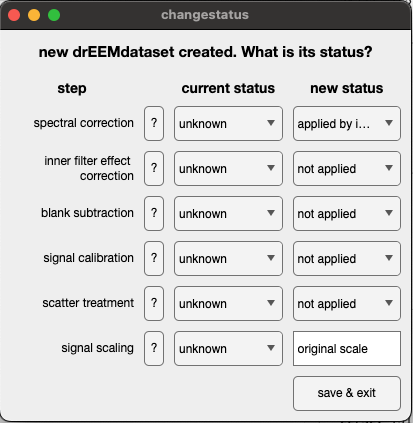

In this case, the default options for the status are appropriate. Note that in your case, the dataset status might differ and you should use this opportunity to provide the correct information. We repeat this step for the blank EEMs and absorbance spectra.

Next, we delete some information from the filenames to demonstrate how this could be done. The string `' (01)'` refers to the first replicate measurement of the sample. In this example, this information is irrelevant and can be deleted. If a sample was remeasured for some reason, a string `' (02)'` remains in the filename to let us know.

samples.filelist=erase(samples.filelist,{' (01)'});
blanks.filelist=erase(blanks.filelist,{' (01)'});
absorbance.filelist=erase(absorbance.filelist,{' (01)'});
samples=tbx.addcomment(samples,"Erased the ' (01)' string pattern from sample names.");

This is a manual dataset modification in the broadest sense. In the spirt of reproducibility and tracability, we leave a comment in the dataset to remind us of what was done.

## Dataset alignment

It is entirely possible that one of the three files went missing in some cases for some samples. Before we continue, we need to make sure that only complete triplets remain in the three datasets.

[samples,blanks,absorbance]=tbx.alignsamples(samples,blanks,absorbance);

samples: removed 1 samples with the previous .i: 10
blanks: removed 1 samples with the previous .i: 10
absorbance: No action necessary. All files between supplied datasets had same names.


This is ensured with the function [`alignsamples`](matlab:open('alignsamples.html')). It compares the contents of the variable `filelist` within each [`drEEMdataset`](matlab:open('dreemdataset.html')) supplied. Again, in the case of the "simple" tutorial here, the filenames are all identical after the import, so this step should not be difficult.

But as you can see from the console output, one sample was removed in the sample and blank EEM datasets. This was caused by a missing absorbance file. Either we could try to find it or just accept that this particular sample will be ommited.

At this stage, it is safe to transfer the absorbance data into the sample dataset to cut down on the Workspace variables:

samples.absWave=absorbance.absWave;
samples.abs=absorbance.abs;
tbx.validatedataset(samples);
clearvars absorbance
samples=tbx.addcomment(samples,"transferred absorbance to the sample EEM dataset");

We leave a comment in the dataset's history to remind ourselves of what we have done using [`addcomment`](matlab:open('addcomment')). In fact, we can take a look at the dataset's history with [`displayhistory`](matlab:open('displayhistory.html')) to demonstrate how this could be useful:

tbx.displayhistory(samples)

    #        Function                             User comment                                        Function message               
    _    ________________    ______________________________________________________    ______________________________________________

    1    {'importeems'  }    "Erased the ' (01)' string pattern from sample names."    {'created dataset'                           }
    2    {'alignsamples'}    "transferred absorbance to the sample EEM dataset"        {'removed 1 samples with the previous .i: 10'}



You could also use the GUI tool [`viewhistory`](matlab:open('viewhistory')) for this:

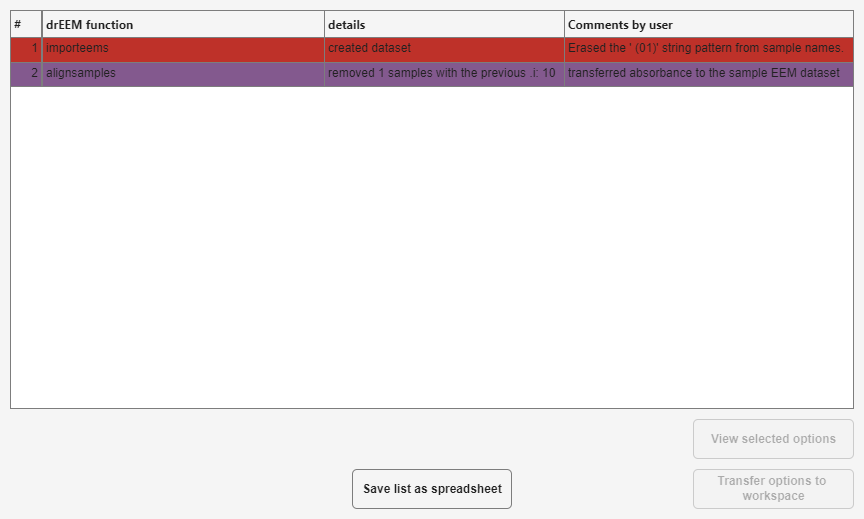

tbx.viewhistory(samples)

The color coding in the GUI tool is designed to distinguish between different functions. I.e. if you called subdataset many times, these lines will have the same color.

We have some metadata that goes along with this dataset. Let's load it, look at it, and then merge it into the dataset:

associatemetadata_output.png

       date         time       sampleId           location           latitude    longitude    salinity    chlorophyll_a    nitrate    oxygen     pH      temperature    depth
    ___________    _______    __________    _____________________    ________    _________    ________    _____________    _______    ______    _____    ___________    _____

    29-Mar-2016    0.44792    {'LCEP02'}    {'Ilwaco'           }     46.301      -124.05         NaN           NaN           NaN        NaN      NaN         NaN        NaN 
    29-Mar-2016    0.44792    {'LCE

                     drEEMdataset    imported metadata table
                     ____________    _______________________

    No. samples           32                   32           
    Total matched         31                   31           
    % matched             97                   97           



samples =   drEEMdataset with properties:

            history: [3×1 drEEMhistory]
                  X: [32×250×73 double]
                abs: [32×73 double]
        suppSpectra: []
           filelist: {32×1 cell}
                  i: [32×1 double]
                 Ex: [73×1 double]
                 Em: [250×1 double]
                nEx: 73
                nEm: 250
            absWave: [73×1 double]
    suppSpectraAxis: [0×1 double]
            nSample: 32
             models: [0×1 drEEMmodel]
           metadata: [32×15 table]
    opticalMetadata: [0×0 table]
              split: [0×0 drEEMdataset]
             status: [1×1 drEEMstatus]
           userdata: []
     instrumentInfo: [0×0 struct]
    measurementInfo: [0×0 struct]


disp(samples.metadata)

    i     filelist       date         time      sampleId        location         latitude    longitude    salinity    chlorophyll_a    nitrate    oxygen     pH      temperature    depth
    __    ________    ___________    _______    ________    _________________    ________    _________    ________    _____________    _______    ______    _____    ___________    _____

     1    CAMAS01     missing            NaN    missing     missing                  NaN          NaN         NaN    

Now we can save the dataset for later use.

save('tutorial_01_imported.mat',"blanks","samples")
disp('Tutorial finished.')

Tutorial finished.


This is the end of the tutorial. If you want to go futher, have a look at the [data processing tutorial](matlab:open('processing_tutorial_01.html')).